# Projecto ABP: Breast Cancer Tumor Diagnosis

## Load Dataset and Create Table

Firstly we need to load in our .data file which contains or Diagnostic Breast Cancer Dataset

%%Initialize variables.
filename = 'wdbc.data';
delimiter = ',';

formatSpec = '%f%C%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string',...
    'ReturnOnError', false);
fclose(fileID);
%SE = Standard Error
data = table(dataArray{1:end-1}, 'VariableNames', {'ID','Diagnosis','Mean_Radius',...
    'Mean_Texture','Mean_Perimeter','Mean_Area','Mean_Smoothness','Mean_Compactness',...
    'Mean_Concavity','Mean_Concave_Points','Mean_Symmetry','Mean_Fractal_Dimension',...
    'Radius_SE','Texture_SE','Perimeter_SE','Area_SE','Smoothness_SE','Compactness_SE',...
    'Concavity_SE','Concave_Points_SE','Symmetry_SE','Fractal_Dimension_SE',...
    'Largest_Radius','Worst_Texture','Largest_Perimeter','Largest_Area',...
    'Worst_Smoothness','Worst_Compactness','Worst_Concavity','Most_Concave_Points',...
    'Worst_Symmerty','Largest_Fractal_Dimension'});

clearvars filename delimiter formatSpec fileID dataArray ans;
data

data = 569×32 table
        ID        Diagnosis    Mean_Radius    Mean_Texture    Mean_Perimeter    Mean_Area    Mean_Smoothness    Mean_Compactness    Mean_Concavity    Mean_Concave_Points    Mean_Symmetry    Mean_Fractal_Dimension    Radius_SE    Texture_SE    Perimeter_SE    Area_SE    Smoothness_SE    Compactness_SE    Concavity_SE    Concave_Points_SE    Symmetry_SE    Fractal_Dimension_SE    Largest_Radius    Worst_Texture    Largest_Perimeter    Largest_Area    Worst_Smoothness    Worst_Compactness    Wo

We get a table with all our 32 different attributes. The second column defines the classification of our data into benign(= harmless) and malignant (= Dangerous). To use our data we need to further process our dataset.

## Preprosessing of dataset

The next step is to clean our data up a bit and prepare the data for our analysis. In order to do so we start with getting rid of the ID and also are going to split our data into attributes and class identification.

data = data(:, 2:32);
X = data(:,2:31); 
Y = data(:, 1);

Since the standerization of the data takes place while training the model there is no need to do it now.

## Develop predictive models

We are going to use the Classification Learner App to interactively train, compare and select classifiers. For validation we are using a 5-fold Cross Validation.

classificationLearner

After training all the models, we see that the Support Vector Machines Tend to give the best results using all of our 30 features. 

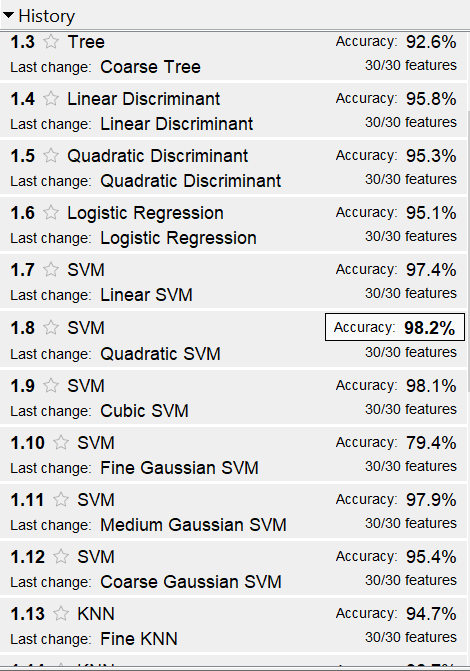

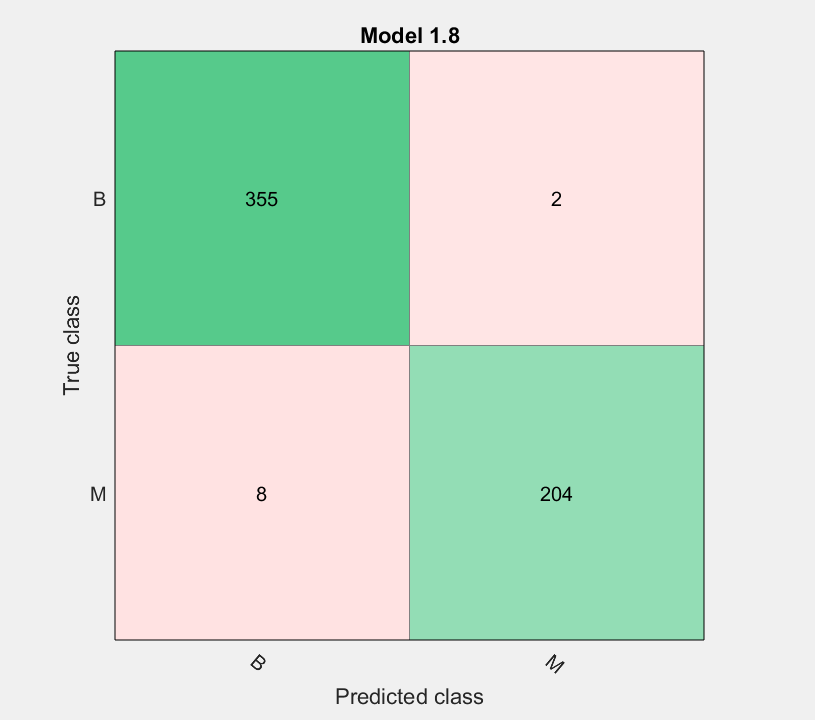

If we look at the confusion matrix this model works quite good with our dataset but there a still to many numbers of malignant (dangerous) tumors are misclassified as benign (harmless), which is very undesirable in medical practice because it means failing to diagnose someone who might have a serious tumor condition. To improve model performance, the following sections will apply additional optimization steps.

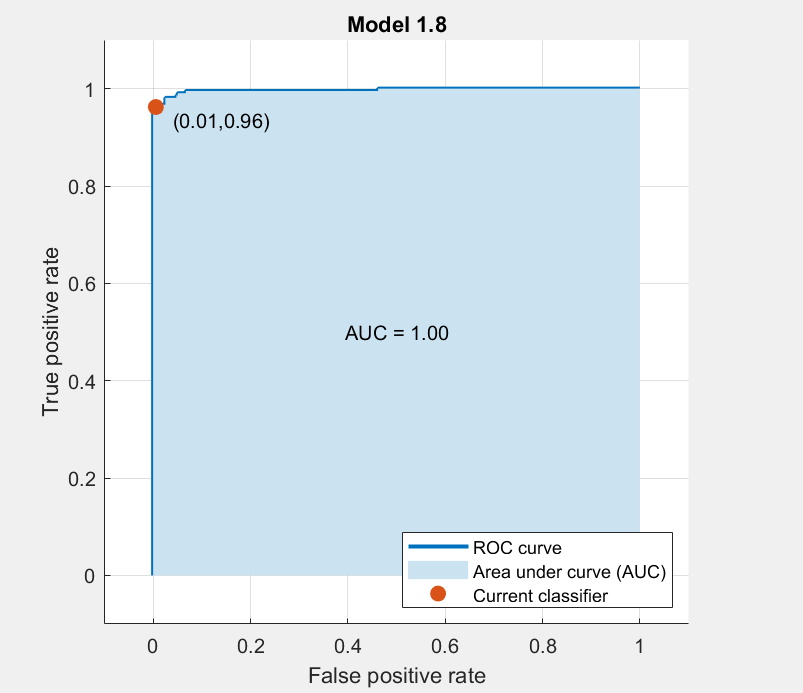

This Receiver Operating Characteristic curve with malignand as being the positive class shows again, that performance on predicting positive benigns would be nearly perfect, but we want to have nearly perfect positive malignand diagnoses, so we will have to give the predicting model a bias. In terms of the ROC curve it means we will have to move the red dot, the current classifier to the right. We can already see, that this will come a quiet a cost with the prediction of positive benigns. 

## Split data into training and test sets

Here we prepare our data for training and testing programmaticaly. We use cvpartition to split the data into training and test sets. Hold-out helps to devide the data randomly into 30% test data and 70% training data. Besides that we also check our dataset for how many diagnosis belong to each class.

rng(1);
%split data
splitData = cvpartition(data.Diagnosis, 'Holdout', 0.3);
training = data(splitData.training, :);
test = data(splitData.test, :);
%count number of Benign and Malignant entries in our Dataset
ccat = countcats(data.Diagnosis);
counts = sprintf("Benign = %d \nMalignant = %d",ccat(1), ccat(2));
disp(counts)

Benign = 357 
Malignant = 212


## Train the classifier with misclassification costs

In order to prevent misclassified dangerous tumors further we increase the misclassifiction costs with the 'Malignant' class. Knowing we tend to get the best results with Support Vector Machines (SVM) we will perform hyperparameter tuning by using Baysian Optimization to further improve our predictive power.

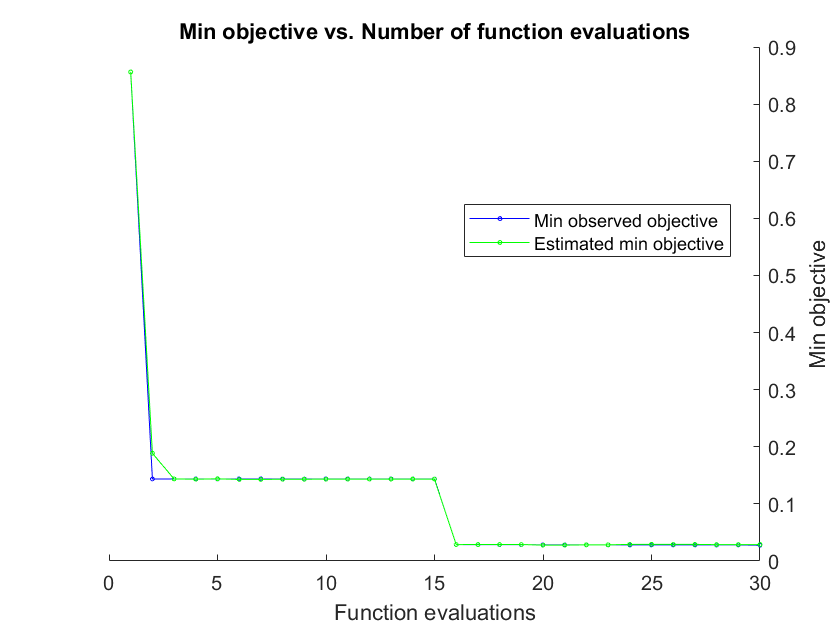

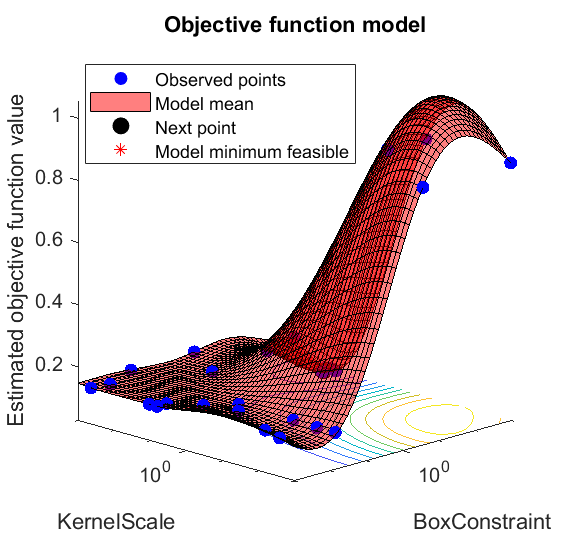

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    | t            |              |
|=====================================================================================================|
|    1 | Best   |     0.85632 |     0.13439 |     0.85632 |     0.85632 |       88.096 |      0.23478 |
|    2 | Best   |     0.14368 |    0.096651 |     0.14368 |     0.18861 |    0.0077583 |      0.27445 |
|    3 | Accept |     0.14368 |    0.085935 |     0.14368 |     0.14366 |     0.027654 |       942.21 |
|    4 | Accept |     0.14368 |     0.10788 |     0.14368 |     0.14327 |    0.0013772 |     0.003578 |
|    5 | Accept |     0.14368 |    0.082196 |     0.14368 |     0.14387 |    0.0010005 |       438.55 |
|    6 | Accept |     0.14368 |     0.11778 |     0.14368 |     

model =   ClassificationSVM
                       PredictorNames: {1×30 cell}
                         ResponseName: 'Diagnosis'
                CategoricalPredictors: []
                           ClassNames: [B    M]
                       ScoreTransform: 'none'
                      NumObservations: 399
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [78×1 double]
                                 Bias: 12.2619
                     KernelParameters: [1×1 struct]
                                   Mu: [1×30 double]
                                Sigma: [1×30 double]
                       BoxConstraints: [399×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [399×1 logical]
                               Solver: 'SMO'


  Properties, 

%higher costs for misclassification
C = [0, 1; 10, 0];

subsample = [1:height(training)];
cvp = cvpartition(length(subsample),'KFold', 5);

opts = struct('Optimizer', 'bayesopt', ...
    'ShowPlots', true, ...
    'CVPartition',cvp, ...
    'AcquisitionFunctionName', 'expected-improvement-plus');
rng(1);
model = fitcsvm(training(subsample, :), 'Diagnosis', 'KernelFunction', 'rbf', ...
    'Cost', C, ...
    'Standardize', true, ...
    'OptimizeHyperparameters', 'auto', ...
    'HyperparameterOptimizationOptions', opts)


save('TrainedSVMModel', 'model');

After training and fitting our model we need to check how well it does predicting our test data. So here we plot a confusion map to get an impression of our error rate.

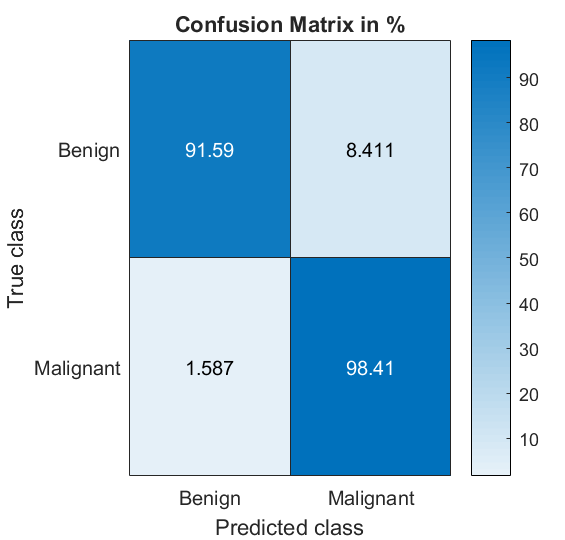

predicted_class = predict(model, test);
conf_mat = confusionmat(test.Diagnosis, predicted_class);
conf_mat_per = conf_mat*100./sum(conf_mat, 2);
labels = {'Benign','Malignant'};
h = heatmap(labels, labels, conf_mat_per);
h.XLabel = 'Predicted class';
h.YLabel = 'True class';
h.Title = 'Confusion Matrix in %';

## Feature Selection

Since reducing the dimensionality and redundancies may help against overfitting and also saves some computational power it makes sense to have a look at that.

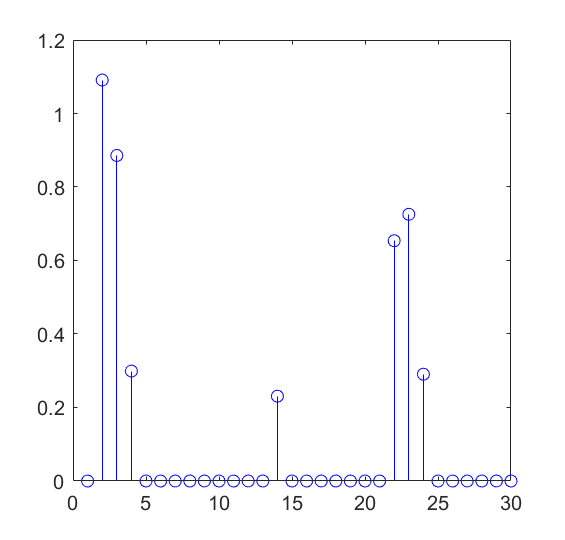

mdl = fscnca(table2array(training(:,2:31)), ...
        table2array(training(:,1)), 'Lambda', 0.005, 'Verbose', 0);
    
    % Select features with weight above 0.5
    selected_feature_indx = find(mdl.FeatureWeights > 0.05);

    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');

    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx');
    % Display list of selected features
disp(data.Properties.VariableNames(selected_feature_indx))

  Column 1

    'Mean_Radius'

  Column 2

    'Mean_Texture'

  Column 3

    'Mean_Perimeter'

  Column 4

    'Perimeter_SE'

  Column 5

    'Largest_Radius'

  Column 6

    'Worst_Texture'

  Column 7

    'Largest_Perimeter'



We see that these 7 attributes tend to have by far the greates impact on our results. The next step is retrain a model only with those seven attributes and check if our system has improved his predictive power.

## Retraining the model with the selected Attributes

Now we train another model with our new feature selection. This way we check if our prior model was overfitting the data.

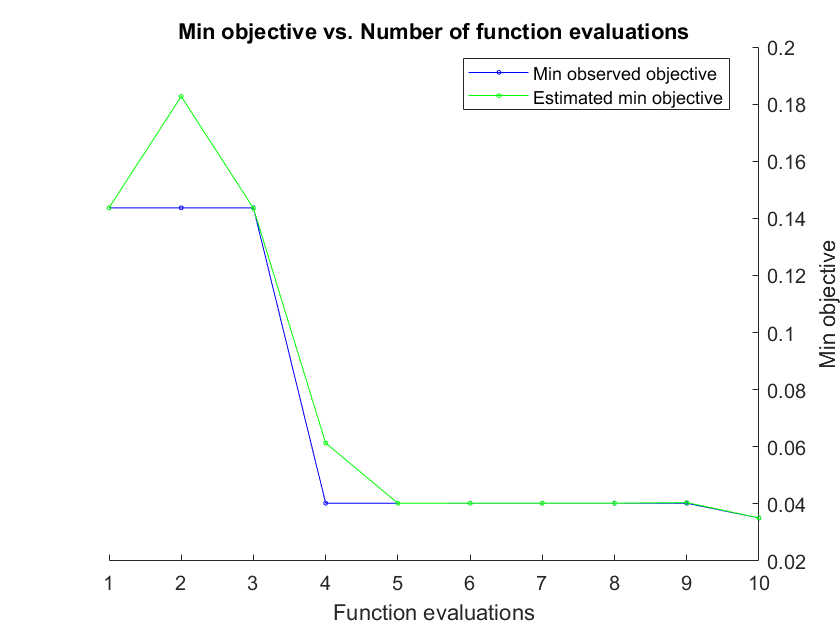

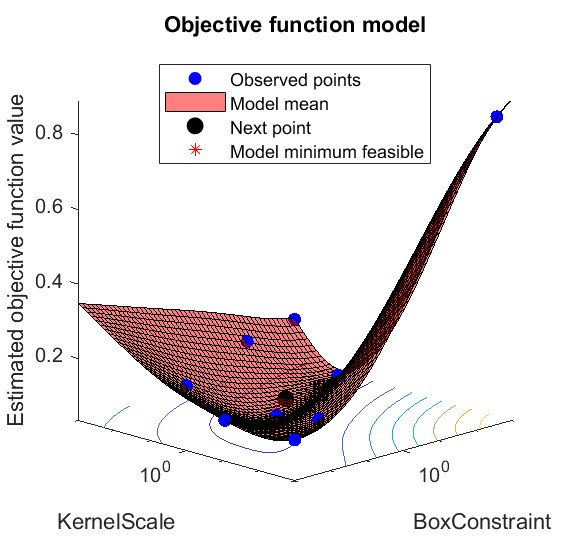

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    | t            |              |
|=====================================================================================================|
|    1 | Best   |     0.14368 |     0.11681 |     0.14368 |     0.14368 |      0.01554 |        15.36 |
|    2 | Accept |     0.85632 |     0.13997 |     0.14368 |      0.1827 |       461.04 |    0.0011344 |
|    3 | Accept |     0.14368 |     0.12698 |     0.14368 |     0.14353 |     0.023127 |    0.0049355 |
|    4 | Best   |     0.04023 |    0.081274 |     0.04023 |    0.061314 |          511 |       32.572 |
|    5 | Accept |    0.044828 |    0.084511 |     0.04023 |    0.040206 |       430.26 |       24.212 |
|    6 | Accept |     0.14368 |    0.082324 |     0.04023 |    0

trained_model_featsel =   ClassificationSVM
                       PredictorNames: {'Mean_Radius'  'Mean_Texture'  'Mean_Perimeter'  'Perimeter_SE'  'Largest_Radius'  'Worst_Texture'  'Largest_Perimeter'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [B    M]
                       ScoreTransform: 'none'
                      NumObservations: 399
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [146×1 double]
                                 Bias: 0.6960
                     KernelParameters: [1×1 struct]
                                   Mu: [16.7777 20.9988 110.4837 4.1156 20.0865 28.4934 133.9122]
                                Sigma: [3.6358 3.9196 24.9850 2.7870 4.9042 5.5766 34.0385]
                       BoxConstraints: [399×1 double]
                      ConvergenceInfo: [1×1 struct]
         

rng(1)
cvp = cvpartition(length(subsample),'KFold',5);
C = [0, 1; 10, 0];            
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
        'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',10);    

% training
trained_model_featsel = fitcsvm(training(subsample, selected_feature_indx), training.Diagnosis(subsample), 'KernelFunction', 'rbf', ...
'Cost', C, ...
'Standardize', true, ...
'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', opts)

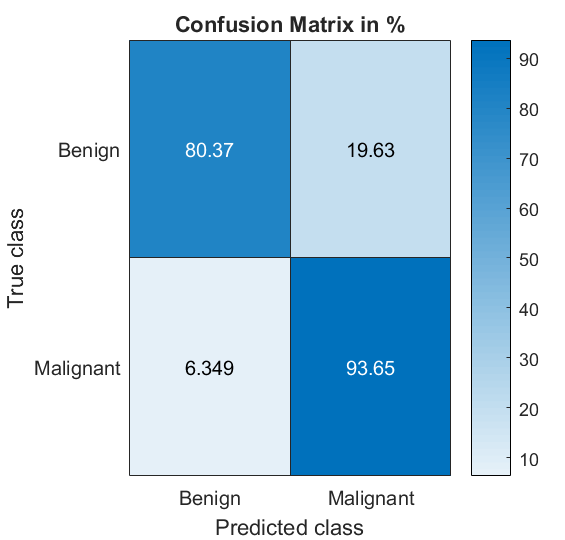

% save the model for later reference
save('TrainedWaveletModel_FeatSel', 'trained_model_featsel');

predicted_class = predict(trained_model_featsel, test);
conf_mat = confusionmat(test.Diagnosis, predicted_class);
conf_mat_per = conf_mat*100./sum(conf_mat, 2);
labels = {'Benign','Malignant'};
h = heatmap(labels, labels, conf_mat_per);
h.XLabel = 'Predicted class';
h.YLabel = 'True class';
h.Title = 'Confusion Matrix in %';

## Conclusion of feature selection

As we can see the performance decreased significantly so we conclude that our prior model was not overfitting our data and had a far better performance that our model with the feature selection. Since computational power is not a problem in a medical environment and its far more important to have maximum precicion it is best to continue with our model using all 30 features.